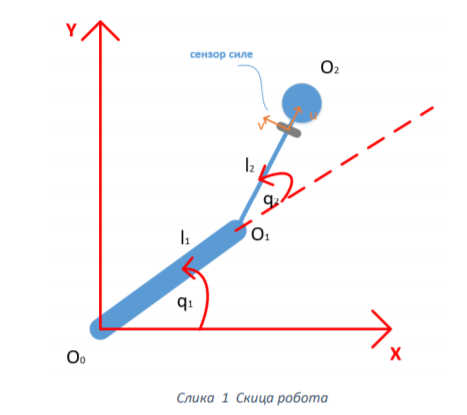

syms l_1 l_2 q_1 q_2 m_1 m_2
x = l_1*cos(q_1)+l_2*cos(q_2+q_1)

$$x = l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)$$

y = l_1*sin(q_1)+l_2*sin(q_2+q_1)

$$y = l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)$$

J(1,1) = diff(x,q_1);
J(2,1) = diff(y,q_1);
J(1,2) = diff(x,q_2);
J(2,2) = diff(y,q_2);
J

$$J = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$


syms q_dot_1 q_dot_2 q_ddot_1 q_ddot_2
vx = -l_1*sin(q_1)*q_dot_1+l_2*sin(q_2+q_1)*(q_dot_1+q_dot_2);
vy = l_1*cos(q_1)*q_dot_1+l_2*cos(q_2+q_1)*(q_dot_1+q_dot_2);
v2=simplify(sqrt(vx^2+vy^2))

$$v2 = \sqrt{{\left(l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\right)}^{2}+{\left(l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)-l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\right)}^{2}}$$

Ek = simplify(1/2*m_1*(q_dot_1*l_1/2)^2+1/2*m_2*v2^2)

$$Ek = \frac{m_{2}\,\left({\left(l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\right)}^{2}+{\left(l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)-l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\right)}^{2}\right)}{2}+\frac{{l_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}}{8}$$

L=Ek;


eq1=simplify(diff(L,q_dot_1))-diff(L,q_1)

$$eq1 = \begin{array}{l} \frac{m_{2}\,\left(2\,\left(\sigma_{5}+\sigma_{2}\right)\,\left(\sigma_{4}+\sigma_{1}\right)-2\,\left(\sigma_{5}-\sigma_{2}\right)\,\left(\sigma_{4}-\sigma_{1}\right)\right)}{2}+\frac{{l_{1}}^{2}\,m_{1}\,{\dot{q}}_{1}}{4}+{l_{1}}^{2}\,m_{2}\,{\dot{q}}_{1}+{l_{2}}^{2}\,m_{2}\,{\dot{q}}_{1}+{l_{2}}^{2}\,m_{2}\,{\dot{q}}_{2}+2\,l_{1}\,l_{2}\,m_{2}\,{\dot{q}}_{1}\,\sigma_{3}+l_{1}\,l_{2}\,m_{2}\,{\dot{q}}_{2}\,\sigma_{3}\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ \sigma_{2}=l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ \sigma_{3}=\cos\left(2\,q_{1}+q_{2}\right)\\ \sigma_{4}=l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\\ \sigma_{5}=l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) \end{array}$$

collect(eq1,diff(q_1,t,2))

Unrecognized function or variable 't'.